# Program 2.3

# Linear Convolution using DFT

x = [1 2] ;
h = [2 1] ;

x1 = [x zeros(1, length(h) - 1)] ;
h1 = [h zeros(1, length(x) - 1)] ;

X = fft(x1) ;
H = fft(h1) ;

y = X.*H ;
y1 = ifft(y) ;

disp('The linear convolution of given sequence is: ') ;

The linear convolution of given sequence is: 


disp(y1) ;

     2     5     2



# Program 2.4

# Circular Convolution using DFT based approach

x1 = [1 2 0 1] ;
x2 = [2 2 1 1] ;

d4 = [1 1 1 1 ; 1 -1j  -1 1j ; 1 -1 1 -1 ; 1 1j -1 -1j] ;

x11 = d4 * x1' ;
x21 = d4 * x2' ;
X = x11 .* x21 ;
x = conj((d4) * X/4) ;

disp('Circular Convolution using DFT method: ') ;

Circular Convolution using DFT method: 


disp(x') ;

     6     5     6     7




x3 = cconv(x1, x2, 4) ;
disp('Circular Convolution using time domian method: ') ;

Circular Convolution using time domian method: 


disp(x3) ;

     6     7     6     5



# Program 2.5

# Computation of correlation

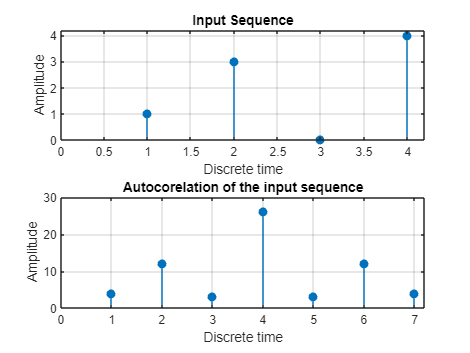

x1 = [1 3 0 4] ;
subplot(2,1,1) ;
stem(x1,'filled') ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Input Sequence') ;
grid on
axis([0 4.2 0 4.2]) ;

y = xcorr(x1, x1) ;
subplot(2,1,2) ;
stem(y,'filled') ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Autocorelation of the input sequence') ;
grid on
axis([0 7.2 0 30]) ;